# Marginal cost data regression using CVX

## Load cleaned marginal cost data

load("cleanedQMCTables.mat");

## Fit linear relation using CVX

linearCVX = zeros(numSelParts, 2);
for n = 1:numSelParts
    cleanedMC = selCleanedPartQMCTables{n}.MCMarket;
    cleanedQuantity = selCleanedPartQMCTables{n}.Awarded;
    cvx_begin quiet
        variable a1
        variable a0
        minimize(norm(cleanedMC - (a1*cleanedQuantity + a0)));
    cvx_end
    selCleanedPartQMCTables{n}.linearFit = a1*cleanedQuantity + a0;
    selCleanedPartQMCTables{n}.linearError = selCleanedPartQMCTables{n}.MCMarket - selCleanedPartQMCTables{n}.linearFit;
    linearCVX(n, :) = [a1, a0];
end

## Visualize linear fit relation

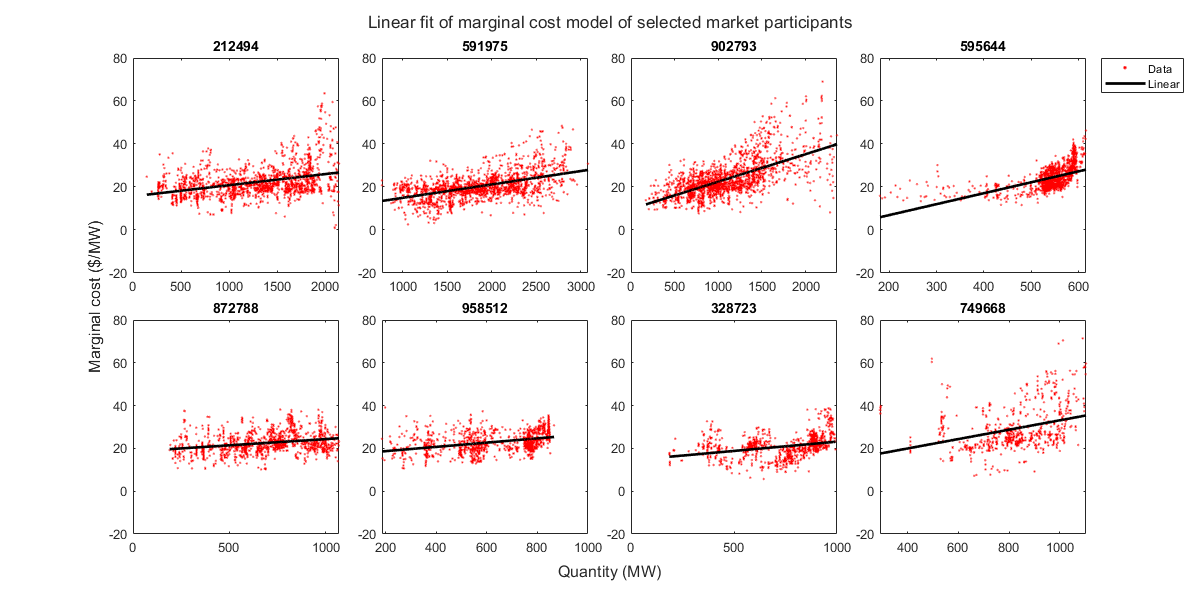

% Plot quantity vs marginal cost of selected market participants
plotColumn = 4;
t = tiledlayout(numSelParts/plotColumn, plotColumn, "TileSpacing","compact");
for n = 1:numSelParts
    nexttile;
    partCleanedQMCTable = selCleanedPartQMCTables{n};
    partID = selPartIDs(n);
    scatter(partCleanedQMCTable.Awarded, partCleanedQMCTable.MCMarket, 10, 'r.');
    hold on;
    % Plot quadratic estimation
    plot(partCleanedQMCTable.Awarded, partCleanedQMCTable.linearFit, 'k-', 'Linewidth', 2);
    hold off; box on;
    title(partID);
    ylim([-20, 80]);
    if n==plotColumn
        legend(["Data", "Linear"], "Location", "bestoutside");
    end
end
xlabel(t, "Quantity (MW)");
ylabel(t, "Marginal cost ($/MW)");
title(t, "Linear fit of marginal cost model of selected market participants");
set(gcf, "Position", [50, 50, 1200, 600]);
saveas(gcf, "../model_output/figures/MCLinearCVX.png");

## Fit quadratic relation using CVX

quadCVX = zeros(numSelParts, 3);
for n = 1:8
    cleanedMC = selCleanedPartQMCTables{n}.MCMarket;
    cleanedQuantity = selCleanedPartQMCTables{n}.Awarded;
    cvx_begin quiet
        variable b2
        variable b1
        variable b0
        minimize(norm(cleanedMC-(b2*cleanedQuantity.^2 + b1*cleanedQuantity + b0)));
    cvx_end
    selCleanedPartQMCTables{n}.quadFit = b2*cleanedQuantity.^2 + b1*cleanedQuantity + b0;
    selCleanedPartQMCTables{n}.quadError = selCleanedPartQMCTables{n}.MCMarket - selCleanedPartQMCTables{n}.quadFit;
    quadCVX(n, :) = [b2, b1, b0];
end

## Visualize quadratic fit relation

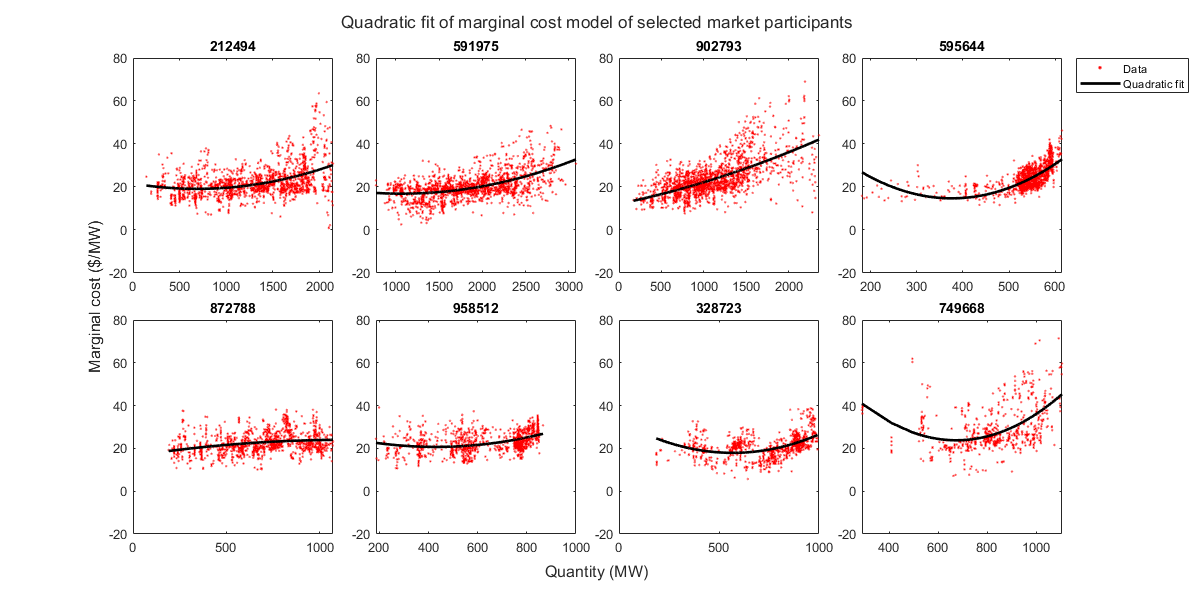

% Plot quantity vs marginal cost of selected market participants
plotColumn = 4;
t = tiledlayout(numSelParts/plotColumn, plotColumn, "TileSpacing","compact");
for n = 1:numSelParts
    nexttile;
    partCleanedQMCTable = selCleanedPartQMCTables{n};
    partID = selPartIDs(n);
    scatter(partCleanedQMCTable.Awarded, partCleanedQMCTable.MCMarket, 10, 'r.');
    hold on;
    % Plot quadratic estimation
    plot(partCleanedQMCTable.Awarded, partCleanedQMCTable.quadFit, 'k-', 'Linewidth', 2);
    hold off; box on;
    title(partID);
    ylim([-20, 80]);
    if n==plotColumn
        legend(["Data", "Quadratic fit"], "Location", "bestoutside");
    end
end
xlabel(t, "Quantity (MW)");
ylabel(t, "Marginal cost ($/MW)");
title(t, "Quadratic fit of marginal cost model of selected market participants");
set(gcf, "Position", [50, 50, 1200, 600]);
saveas(gcf, "../model_output/figures/MCQuadCVX.png");

## Fit quadratic relation using CVX

cubicCVX = zeros(numSelParts, 4);
for n = 1:8
    cleanedMC = selCleanedPartQMCTables{n}.MCMarket;
    cleanedQuantity = selCleanedPartQMCTables{n}.Awarded;
    cvx_begin quiet
        variable c3
        variable c2
        variable c1
        variable c0
        minimize(norm(cleanedMC-(c3*cleanedQuantity.^3 + c2*cleanedQuantity.^2 + c1*cleanedQuantity + c0)));
    cvx_end
    selCleanedPartQMCTables{n}.cubicFit = c3*cleanedQuantity.^3 + c2*cleanedQuantity.^2 + c1*cleanedQuantity + c0;
    selCleanedPartQMCTables{n}.cubicError = selCleanedPartQMCTables{n}.MCMarket - selCleanedPartQMCTables{n}.cubicFit;
    cubicCVX(n, :) = [c3, c2, c1, c0];
end

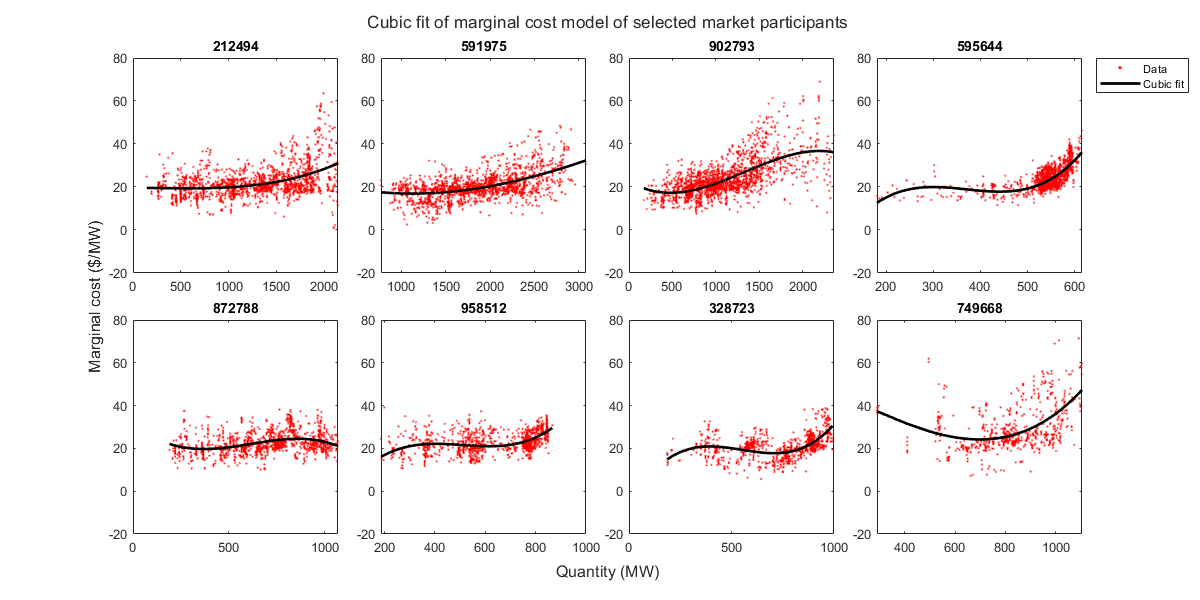

% Plot quantity vs marginal cost of selected market participants
plotColumn = 4;
t = tiledlayout(numSelParts/plotColumn, plotColumn, "TileSpacing","compact");
for n = 1:numSelParts
    nexttile;
    partCleanedQMCTable = selCleanedPartQMCTables{n};
    partID = selPartIDs(n);
    scatter(partCleanedQMCTable.Awarded, partCleanedQMCTable.MCMarket, 10, 'r.');
    hold on;
    % Plot quadratic estimation
    plot(partCleanedQMCTable.Awarded, partCleanedQMCTable.cubicFit, 'k-', 'Linewidth', 2);
    hold off; box on;
    title(partID);
    ylim([-20, 80]);
    if n==plotColumn
        legend(["Data", "Cubic fit"], "Location", "bestoutside");
    end
end
xlabel(t, "Quantity (MW)");
ylabel(t, "Marginal cost ($/MW)");
title(t, "Cubic fit of marginal cost model of selected market participants");
set(gcf, "Position", [50, 50, 1200, 600]);
saveas(gcf, "../model_output/figures/MCCubicCVX.png");

## Show fitness of the regression models

corrLinear = zeros(numSelParts, 1);
corrQuad = zeros(numSelParts, 1);
corrCubic = zeros(numSelParts, 1);
RMSELinear = zeros(numSelParts, 1);
RMSEQuad = zeros(numSelParts, 1);
RMSECubic = zeros(numSelParts, 1);
for n=1:numSelParts
    partCleanedQMCTable = selCleanedPartQMCTables{n};
    % Calculate correlation coefficient
    linearR = corrcoef(partCleanedQMCTable.MCMarket, partCleanedQMCTable.linearFit);
    quadR= corrcoef(partCleanedQMCTable.MCMarket, partCleanedQMCTable.quadFit);
    cubicR = corrcoef(partCleanedQMCTable.MCMarket, partCleanedQMCTable.cubicFit);
    corrLinear(n)= linearR(1, 2);
    corrQuad(n)= quadR(1, 2);
    corrCubic(n) = cubicR(1, 2);
    % Calculate RMSE
    RMSELinear(n) = sqrt(mean(partCleanedQMCTable.linearError.^2));
    RMSEQuad(n) = sqrt(mean(partCleanedQMCTable.quadError.^2));
    RMSECubic(n) = sqrt(mean(partCleanedQMCTable.cubicError.^2));
end
selPartIDs = categorical(selPartIDs);
selPartCorrTableCVX = table(selPartIDs, corrLinear, corrQuad, corrCubic, RMSELinear, RMSEQuad, RMSECubic)

selPartCorrTableCVX = 8×7 table
    selPartIDs    corrLinear    corrQuad    corrCubic    RMSELinear    RMSEQuad    RMSECubic
    __________    __________    ________    _________    __________    ________    _________

      212494        0.3772      0.41861      0.41983        6.456       6.3307      6.3268  
      591975       0.51311      0.53968      0.53975        5.079       4.9817      4.9814  
      902793       0.63589      0.63816      0.64986       6.4023       6.3867       6.305  
      595644       0.54499      0.68828      0.72846       4.3812       3.7907      3.5798  
      872788        0.2761      0.28343      0.33959       4.5929       4.5827      4.4947  
      958512       0.36818      0.41381      0.46948       4.4167       4.3246

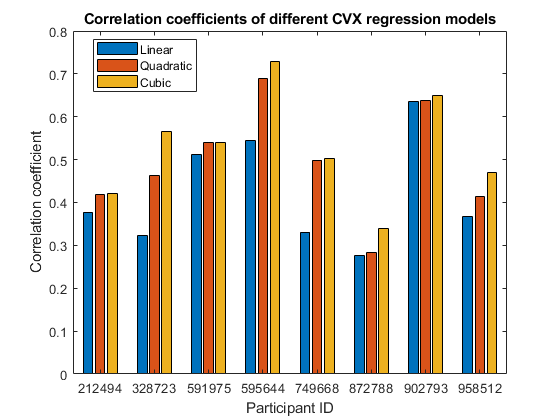

figure;
bar(selPartIDs, [corrLinear, corrQuad, corrCubic]);
legend(["Linear", "Quadratic", "Cubic"], "Location","best");
xlabel("Participant ID");
ylabel("Correlation coefficient");
title("Correlation coefficients of different CVX regression models");
saveas(gcf, "../model_output/figures/corrCoefCVX.png");

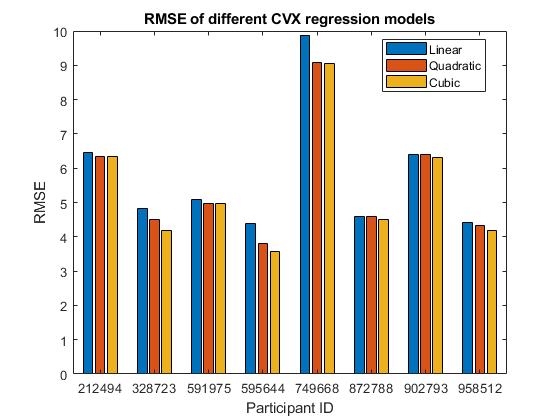

figure;
bar(selPartIDs, [RMSELinear, RMSEQuad, RMSECubic]);
legend(["Linear", "Quadratic", "Cubic"], "Location","best");
xlabel("Participant ID");
ylabel("RMSE");
title("RMSE of different CVX regression models");
saveas(gcf, "../model_output/figures/RMSECVX.png");

## Comparison of CVX and MATLAB polyfit results

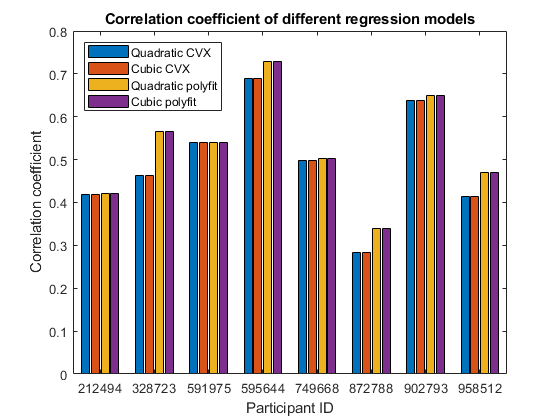

load("polyfitCorrRSME.mat");
figure;
bar(selPartIDs, [corrQuad, selPartCorrPolyfit.corrQuad, corrCubic, selPartCorrPolyfit.corrCubic]);
legend(["Quadratic CVX", "Cubic CVX", "Quadratic polyfit", "Cubic polyfit"], "Location","northwest");
xlabel("Participant ID");
ylabel("Correlation coefficient");
title("Correlation coefficient of different regression models");
saveas(gcf, "../model_output/figures/corrCoefPolyfitCVX.png");

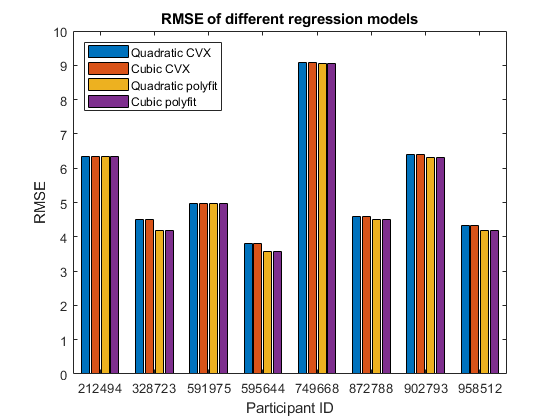

figure;
bar(selPartIDs, [RMSEQuad, selPartCorrPolyfit.RMSEQuad, RMSECubic, selPartCorrPolyfit.RMSECubic]);
legend(["Quadratic CVX", "Cubic CVX", "Quadratic polyfit", "Cubic polyfit"], "Location","northwest");
xlabel("Participant ID");
ylabel("RMSE");
title("RMSE of different regression models");
saveas(gcf, "../model_output/figures/corrCoefPolyfitCVX.png");

## Write fitted models to file

save("MCCVXQuad.mat", "quadCVX", "-mat");
save("MCCVXCubic.mat", "cubicCVX", "-mat");
save("MCCVXResults.mat", "selCleanedPartQMCTables", "-mat");
save("CVXCorrRSME.mat", "selPartCorrTableCVX", "-mat");